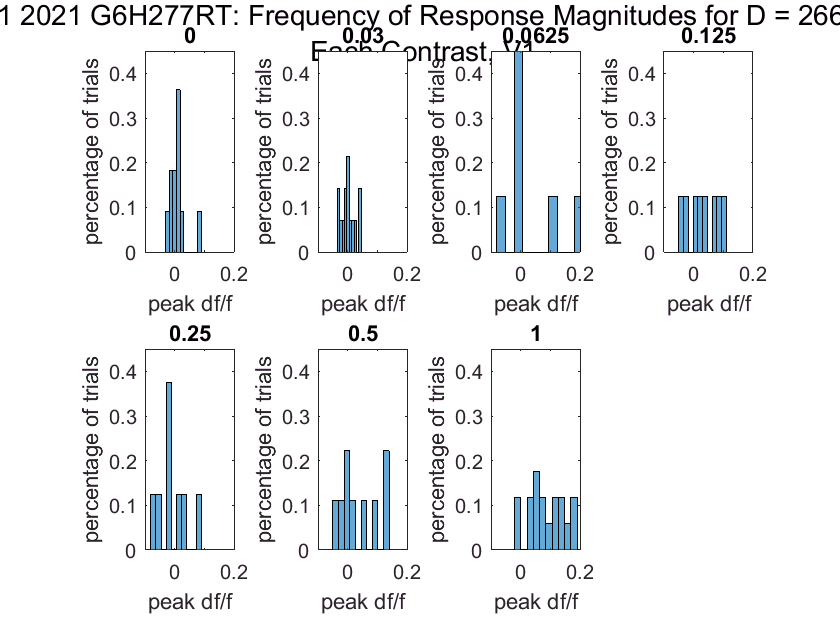

% HISTOS

% HISTO, V1, 266ms, all Con

figure % make one figure for all subplots of each contrast
clear titleText
titleText = sprintf(': Frequency of Response Magnitudes for D = 266 ms \n Each Contrast, V1'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

%for i = 1:length(xpts) % for each point make a figure
for i = 1 % for V1
    
    for d = 5 % the duration param that corresponds to 266 ms
        
    % this is for storing different length-ed cth trial vectors for all sessions (concatenated)
    clear allXCoordinatesAllTrialsOneSessAllStop 
    allSessCthPeakDfEachTrial = []; 
    
    % making the subplots for each contrast
    for c = 1:length(uniqueContrasts) % for each contrast
        
        clear sqOneFrameOverTrialsPTSdfof
        
        % get the DTH CTH TRIALS
        
        clear cthDthTrials
        cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d); % 5th dur param (4 frames, 266 ms)
        numTrials = sum(cthDthTrials);
        
%         % get the CTH TRIALS
%         clear cthTrials
%         cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c);

        % take df/f data for ith pt, peak frames, cth dth trials
        allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,cthDthTrials)); 
        meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
        % ^ CANT do: store output vectors for each contrast
        % b/c every vectoris a different length (num trials), so can't 'collect'
        % Better to just plot directly on the subplot here
        
        % get BASELINE @ cth trials
        clear allBaselineFrames
        allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,cthDthTrials));
        % get one mean baseline value over all frames & trials
        meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
        meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
        
        % SUBTract BASeline from vector of mean df/f for peak frames, for all cth trials
        meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
        
        subplot(2,4,c) % make a subplot for each contrast
        %title(sprintf('c = %0.3d',contrasts(c)))
        
        numBins = 10;
        % histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins)
        histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins,'Normalization','probability')
        title(uniqueContrasts(c))
        xlabel('peak df/f')
        ylabel('percentage of trials')
        ylim([0 0.45])
        xlim([-0.1 0.2])
        
        hold on  
        
    end 
    
    end
       
end 

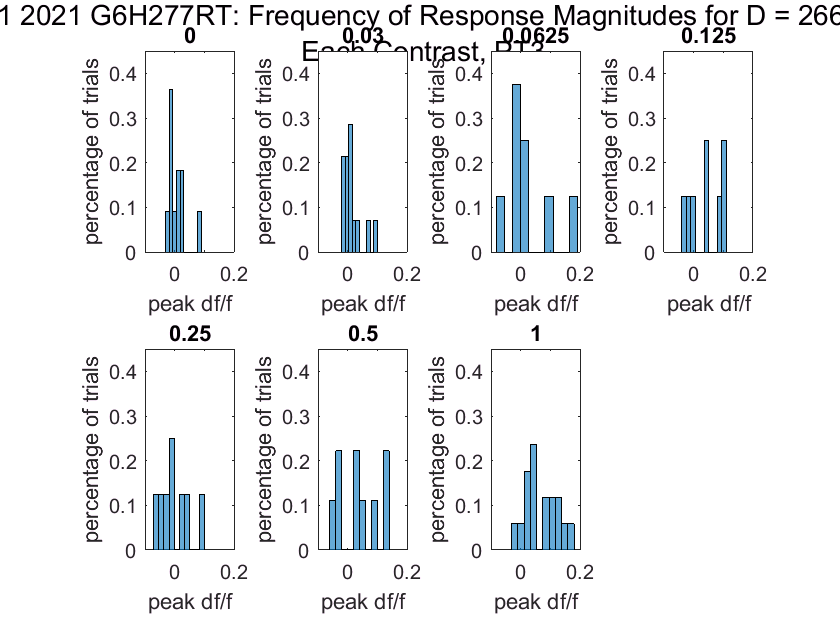

% HISTO, PT3, FULL DURation (266ms), all Con

figure % make one figure for all subplots of each contrast
clear titleText
titleText = sprintf(': Frequency of Response Magnitudes for D = 266 ms \n Each Contrast, PT3'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

%for i = 1:length(xpts) % for each point make a figure
for i = 3 % for PT3
    
    for d = 5 % 266 ms
    
    % making the subplots for each contrast
    for c = 1:length(uniqueContrasts) % for each contrast
        
        clear sqOneFrameOverTrialsPTSdfof
        
        % get the DTH CTH TRIALS
        
        clear cthDthTrials
        cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d); % 5th dur param (4 frames, 266 ms)
        numTrials = sum(cthDthTrials);
        
%         % get the CTH TRIALS
%         clear cthTrials
%         cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c);

        % take df/f data for ith pt, peak frames, cth dth trials
        allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,cthDthTrials)); 
        meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
        % ^ CANT do: store output vectors for each contrast
        % b/c every vectoris a different length (num trials), so can't 'collect'
        % Better to just plot directly on the subplot here
        
        % get BASELINE @ cth trials
        clear allBaselineFrames
        allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,cthDthTrials));
        % get one mean baseline value over all frames & trials
        meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
        meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
        
        % SUBTract BASeline from vector of mean df/f for peak frames, for all cth trials
        meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
        
        subplot(2,4,c) % make a subplot for each contrast
        %title(sprintf('c = %0.3d',contrasts(c)))
        
        numBins = 10;
        % histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins)
        histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins,'Normalization','probability')
        title(uniqueContrasts(c))
        xlabel('peak df/f')
        ylabel('percentage of trials')
        ylim([0 0.45])
        xlim([-0.1 0.2])
        
        hold on  
        
    end 
    
    end
       
end 

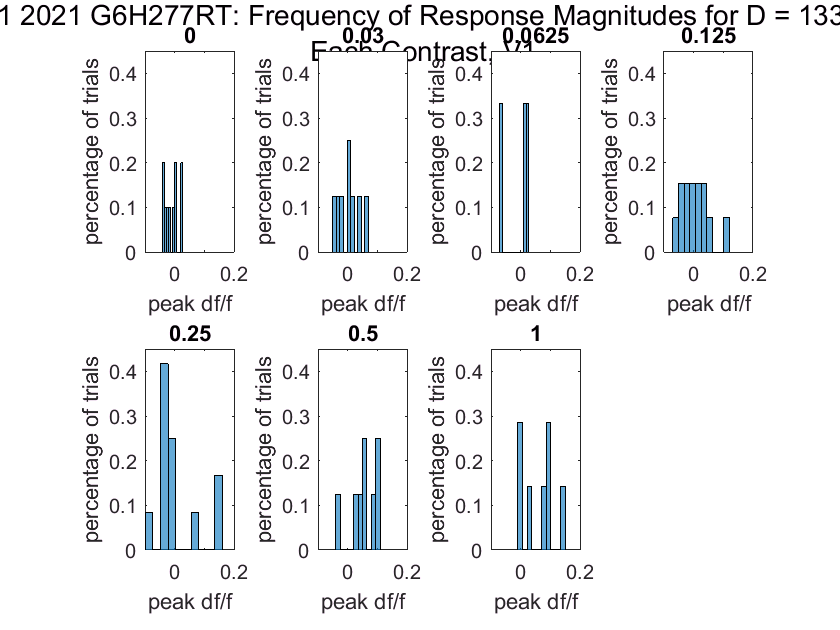

% HISTO, V1, 133 ms, all Con

figure % make one figure for all subplots of each contrast
clear titleText
titleText = sprintf(': Frequency of Response Magnitudes for D = 133 ms \n Each Contrast, V1'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

%for i = 1:length(xpts) % for each point make a figure
for i = 1% for V1
    
    for d = 4 % 133 ms
    
    % making the subplots for each contrast
    for c = 1:length(uniqueContrasts) % for each contrast
        
        clear sqOneFrameOverTrialsPTSdfof
        
        % get the DTH CTH TRIALS
        
        clear cthDthTrials
        cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d); % 5th dur param (4 frames, 266 ms)
        numTrials = sum(cthDthTrials);
        
%         % get the CTH TRIALS
%         clear cthTrials
%         cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c);

        % take df/f data for ith pt, peak frames, cth dth trials
        allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,cthDthTrials)); 
        meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
        % ^ CANT do: store output vectors for each contrast
        % b/c every vectoris a different length (num trials), so can't 'collect'
        % Better to just plot directly on the subplot here
        
        % get BASELINE @ cth trials
        clear allBaselineFrames
        allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,cthDthTrials));
        % get one mean baseline value over all frames & trials
        meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
        meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
        
        % SUBTract BASeline from vector of mean df/f for peak frames, for all cth trials
        meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
        
        subplot(2,4,c) % make a subplot for each contrast
        %title(sprintf('c = %0.3d',contrasts(c)))
        
        numBins = 10;
        % histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins)
        histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins,'Normalization','probability')
        title(uniqueContrasts(c))
        xlabel('peak df/f')
        ylabel('percentage of trials')
        ylim([0 0.45])
        xlim([-0.1 0.2])
        
        hold on  
        
    end 
    
    end
       
end 

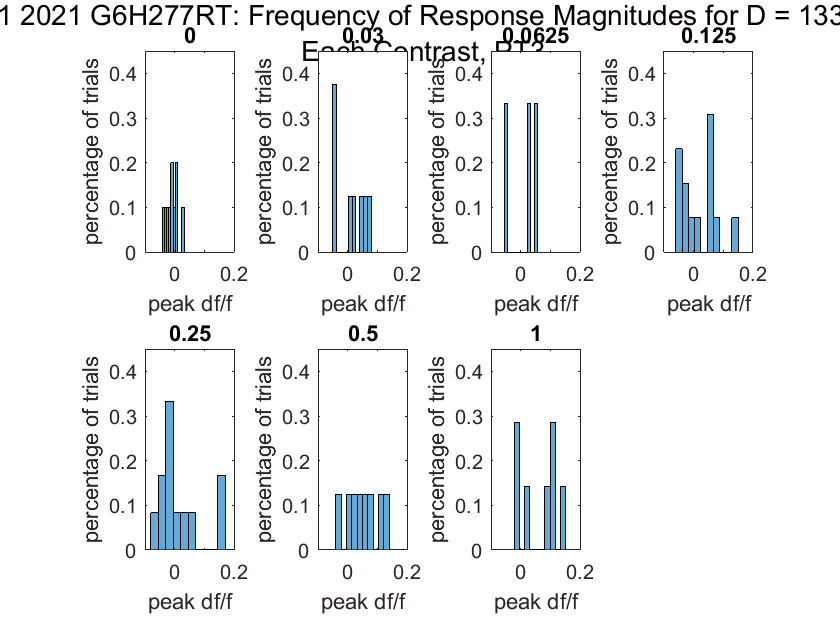

% HISTO, PT3, 133 ms, all Con

figure % make one figure for all subplots of each contrast
clear titleText
titleText = sprintf(': Frequency of Response Magnitudes for D = 133 ms \n Each Contrast, PT3'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

%for i = 1:length(xpts) % for each point make a figure
for i = 3 % for PT3
    
    for d = 4 % 133 ms
    
    % making the subplots for each contrast
    for c = 1:length(uniqueContrasts) % for each contrast
        
        clear sqOneFrameOverTrialsPTSdfof
        
        % get the DTH CTH TRIALS
        
        clear cthDthTrials
        cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d); % 5th dur param (4 frames, 266 ms)
        numTrials = sum(cthDthTrials);
        
%         % get the CTH TRIALS
%         clear cthTrials
%         cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c);

        % take df/f data for ith pt, peak frames, cth dth trials
        allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,cthDthTrials)); 
        meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
        % ^ CANT do: store output vectors for each contrast
        % b/c every vectoris a different length (num trials), so can't 'collect'
        % Better to just plot directly on the subplot here
        
        % get BASELINE @ cth trials
        clear allBaselineFrames
        allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,cthDthTrials));
        % get one mean baseline value over all frames & trials
        meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
        meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
        
        % SUBTract BASeline from vector of mean df/f for peak frames, for all cth trials
        meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
        
        subplot(2,4,c) % make a subplot for each contrast
        %title(sprintf('c = %0.3d',contrasts(c)))
        
        numBins = 10;
        % histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins)
        histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins,'Normalization','probability')
        title(uniqueContrasts(c))
        xlabel('peak df/f')
        ylabel('percentage of trials')
        ylim([0 0.45])
        xlim([-0.1 0.2])
        
        hold on  
        
    end 
    
    end
       
end 

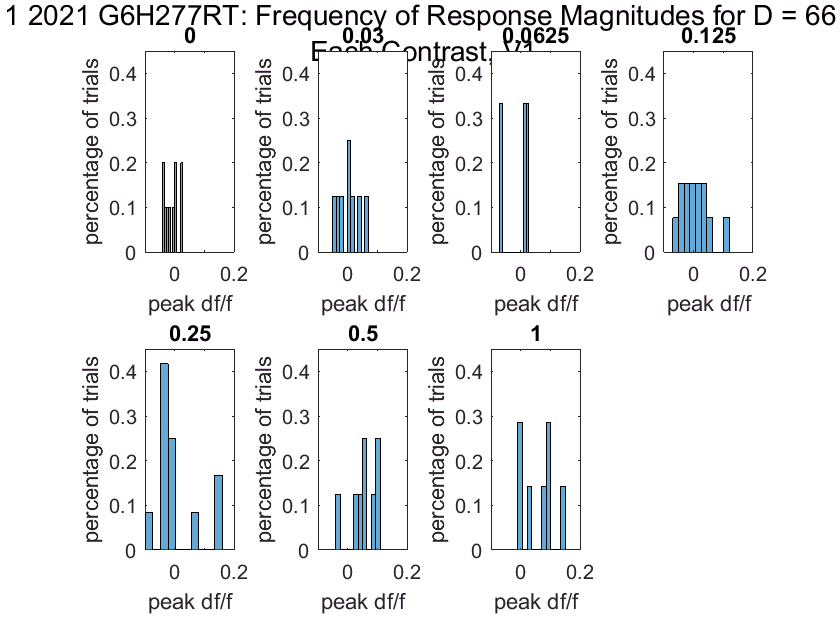

% HISTO, V1, 66 ms, all Con

figure % make one figure for all subplots of each contrast
clear titleText
titleText = sprintf(': Frequency of Response Magnitudes for D = 66 ms \n Each Contrast, V1'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

%for i = 1:length(xpts) % for each point make a figure
for i = 1 % for V1
    
    for d = 4 % 66 ms
    
    % making the subplots for each contrast
    for c = 1:length(uniqueContrasts) % for each contrast
        
        clear sqOneFrameOverTrialsPTSdfof
        
        % get the DTH CTH TRIALS
        
        clear cthDthTrials
        cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d); % 5th dur param (4 frames, 266 ms)
        numTrials = sum(cthDthTrials);
        
%         % get the CTH TRIALS
%         clear cthTrials
%         cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c);

        % take df/f data for ith pt, peak frames, cth dth trials
        allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,cthDthTrials)); 
        meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
        % ^ CANT do: store output vectors for each contrast
        % b/c every vectoris a different length (num trials), so can't 'collect'
        % Better to just plot directly on the subplot here
        
        % get BASELINE @ cth trials
        clear allBaselineFrames
        allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,cthDthTrials));
        % get one mean baseline value over all frames & trials
        meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
        meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
        
        % SUBTract BASeline from vector of mean df/f for peak frames, for all cth trials
        meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
        
        subplot(2,4,c) % make a subplot for each contrast
        %title(sprintf('c = %0.3d',contrasts(c)))
        
        numBins = 10;
        % histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins)
        histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins,'Normalization','probability')
        title(uniqueContrasts(c))
        xlabel('peak df/f')
        ylabel('percentage of trials')
        ylim([0 0.45])
        xlim([-0.1 0.2])
        
        hold on  
        
    end 
    
    end
       
end 

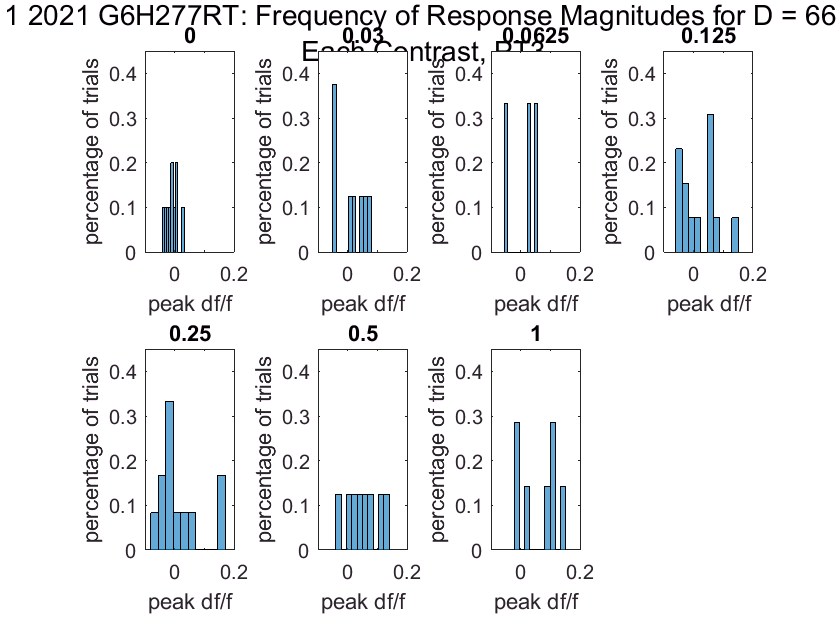

% HISTO, PT3, 66 ms, all Con

figure % make one figure for all subplots of each contrast
clear titleText
titleText = sprintf(': Frequency of Response Magnitudes for D = 66 ms \n Each Contrast, PT3'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

%for i = 1:length(xpts) % for each point make a figure
for i = 3 % for PT3
    
    for d = 4 % 66 ms
    
    % making the subplots for each contrast
    for c = 1:length(uniqueContrasts) % for each contrast
        
        clear sqOneFrameOverTrialsPTSdfof
        
        % get the DTH CTH TRIALS
        
        clear cthDthTrials
        cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d); % 5th dur param (4 frames, 266 ms)
        numTrials = sum(cthDthTrials);
        
%         % get the CTH TRIALS
%         clear cthTrials
%         cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c);

        % take df/f data for ith pt, peak frames, cth dth trials
        allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,cthDthTrials)); 
        meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
        % ^ CANT do: store output vectors for each contrast
        % b/c every vectoris a different length (num trials), so can't 'collect'
        % Better to just plot directly on the subplot here
        
        % get BASELINE @ cth trials
        clear allBaselineFrames
        allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,cthDthTrials));
        % get one mean baseline value over all frames & trials
        meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
        meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
        
        % SUBTract BASeline from vector of mean df/f for peak frames, for all cth trials
        meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
        
        subplot(2,4,c) % make a subplot for each contrast
        %title(sprintf('c = %0.3d',contrasts(c)))
        
        numBins = 10;
        % histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins)
        histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins,'Normalization','probability')
        title(uniqueContrasts(c))
        xlabel('peak df/f')
        ylabel('percentage of trials')
        ylim([0 0.45])
        xlim([-0.1 0.2])
        
        hold on  
        
    end 
    
    end
       
end 

% ALL TRIAL TRACES


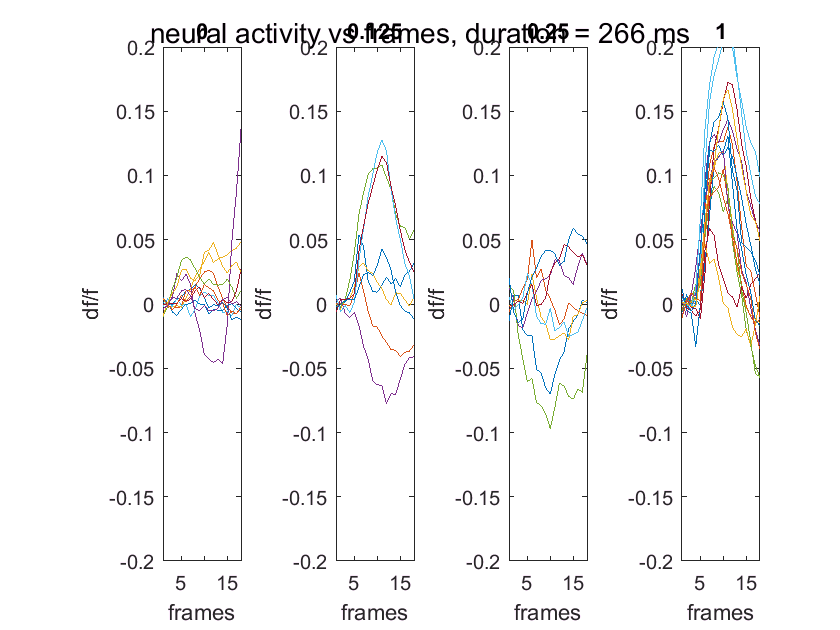

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% V1
% D = 133 ms
% C = 0.125

figure % make one figure for all subplots
clear titleText
titleText = ': df/f vs frames for diff contrasts, dur = 266 ms'; % making char variables for sprintf/title later
% suptitle(sprintf('%s', date, subjName, titleText));
suptitle('neural activity vs frames, duration = 266 ms')

clear i
% for i = 1:length(xPickedPts) % for each point
for i = 1
    
    for d = 5
        
        loopCounter = 1;
        
        for c = [1 4 5 7]
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,cthDthTrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
            for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
            % getting TRIAL VECTOR
            clear onePtAllFramesOneTrial % make new var for each trial
            % index into each trace/vector & save as variable
            onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
            % getting MEAN BASEline VALUE for each TRIAL
            clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
            % collect 4 baseline frames for tr-th ith trial
            allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
            clear mean4baseFramesOnePtOneTrial
            % get mean value of baseline values for ith point
            mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
            mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
            % BASEline CORRECTion of TRIAL VECTOR
            % new baseline-corrected trace for each trial
            onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
        
            % collect CORRECTed TRIAL VECTORS in matrix
            % (only clear this outside the loop for each point)
            recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            
            % plot one baseline corrected trace at a time
            subplot(1,4,loopCounter)
            plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
            title(uniqueContrasts(c))
                
            hold on % hold for next trial
                
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
        ylim([-0.2 0.2]) 
        xlim([1 length(x_axis)])
        ylabel('df/f')
        xlabel('frames')

        ax = gca;
        x.XTick = [1:1:length(x_axis)];
        
        loopCounter = loopCounter + 1;
        
        end % end c loop
        
    end % end d loop
       
end % end i loop

% TRIAL by TRIAL TRACES


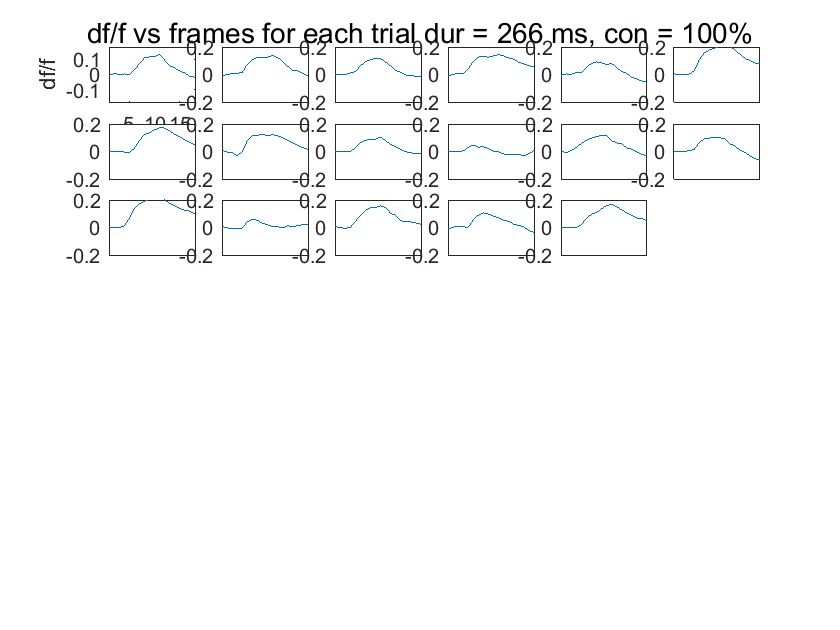

% each trial trace on it's own plot

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% V1
% D = 266 ms
% C = 0.125

figure % make one figure for all subplots
clear titleText
% titleText = ': df/f vs frames for each trial dur = 266 ms, con = 100%'; % making char variables for sprintf/title later
% suptitle(sprintf('%s', date, subjName, titleText));
suptitle('df/f vs frames for each trial dur = 266 ms, con = 100%')

clear i
% for i = 1:length(xPickedPts) % for each point
for i = 1
    
    for d = 5 % 266 ms
        
        loopCounter = 1;
        
        for c = 7 % 100%
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,cthDthTrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
            
            for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
                % getting TRIAL VECTOR
                clear onePtAllFramesOneTrial % make new var for each trial
                % index into each trace/vector & save as variable
                onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
            % getting MEAN BASEline VALUE for each TRIAL
            clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
            % collect 4 baseline frames for tr-th ith trial
            allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
            clear mean4baseFramesOnePtOneTrial
            % get mean value of baseline values for ith point
            mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
            mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
            % BASEline CORRECTion of TRIAL VECTOR
            % new baseline-corrected trace for each trial
            onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
        
            % collect CORRECTed TRIAL VECTORS in matrix
            % (only clear this outside the loop for each point)
            recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            
            % plot one baseline corrected trace at a time
            % roughly, sq
            % there's 47 trials
            % onePtAllFramesAndTrials is trials x frames
            numTrials =  size(onePtAllFramesAndTrials,1); % number of trials
            
            % max of peak frames (stim onset) minus min of all frames after frame 12 (end of peak response reigon)
            peak2post = max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx)) - min(onePtAllFramesOneTrialMinusMeanBase(1,12:end));
            
            % y_range = max(onePtAllFramesOneTrialMinusMeanBase)-min(onePtAllFramesOneTrialMinusMeanBase);
            % peak2postNorm = peak2post/y_range;
            % peak2postDivRangeMult100Percent = peak2postNorm*100;
            % maxOfPeakFrames =  max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx));
             
            % subplot(round(sqrt(size(onePtAllFramesAndTrials,1)))+1,round(sqrt(size(onePtAllFramesAndTrials,1)))+1,loopCounter) % put loop counter at end of tr loop now, so each trial has own subplot
            subplot(7,6,tr)
            plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
            % title(sprintf('max(peak)-min(post) = %0.002f %',peak2post))
            % title(sprintf('%0.003f',peak2post))
            
            if tr == 1
                
                ylim([-0.18 0.18]) 
                xlim([1 length(x_axis)])
                ylabel('df/f')
                xlabel('frames')
                ax = gca;
                x.XTick = [1:1:length(x_axis)];
                
            else
                
                ylim([-0.2 0.2]) 
                xlim([1 length(x_axis)])
                set(gca,'XTick',[])
                
            end 
                
            % don't hold for next trial - plot each trial on own subplot
                
            loopCounter = loopCounter + 1;
            
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
%         ylim([-0.15 0.15]) 
%         xlim([1 length(x_axis)])
%         ylabel('df/f')
%         xlabel('frames')

%         ax = gca;
%         x.XTick = [1:1:length(x_axis)];
        
        end % end c loop
        
    end % end d loop
       
end % end i loop

% ALL TRIALS ALL TRACES w/DARKER trials


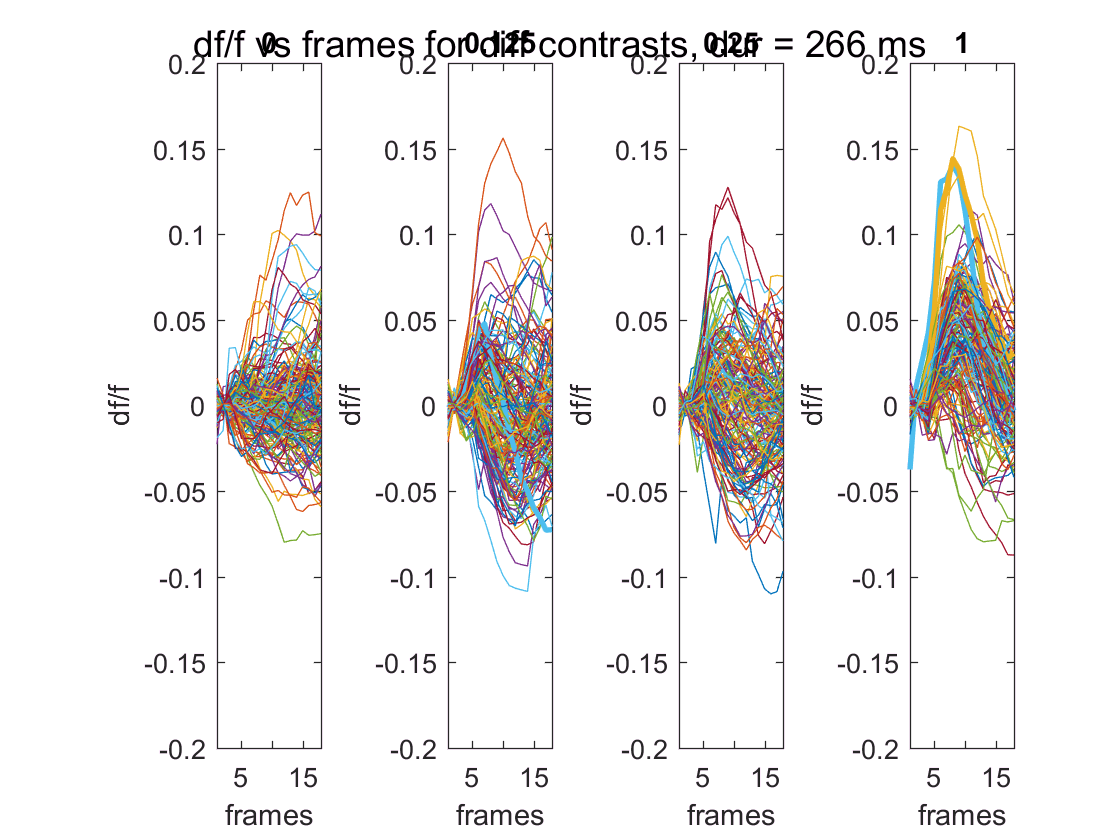

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% V1
% D = 266 ms
% C = 0.125

figure % make one figure for all subplots
clear titleText
titleText = ': df/f vs frames for diff contrasts, dur = 266 ms'; % making char variables for sprintf/title later
% suptitle(sprintf('%s', date, subjName, titleText));
suptitle('df/f vs frames for diff contrasts, dur = 266 ms')

clear i
% for i = 1:length(xPickedPts) % for each point
for i = 1
    
    for d = 1
        
        loopCounter = 1;
        
        for c = [1 4 5 7]
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,cthDthTrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
            for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
            % getting TRIAL VECTOR
            clear onePtAllFramesOneTrial % make new var for each trial
            % index into each trace/vector & save as variable
            onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
            % getting MEAN BASEline VALUE for each TRIAL
            clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
            % collect 4 baseline frames for tr-th ith trial
            allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
            clear mean4baseFramesOnePtOneTrial
            % get mean value of baseline values for ith point
            mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
            mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
            % BASEline CORRECTion of TRIAL VECTOR
            % new baseline-corrected trace for each trial
            onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
            
            peak2post = max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx)) - min(onePtAllFramesOneTrialMinusMeanBase(1,12:end));
        
            % collect CORRECTed TRIAL VECTORS in matrix
            % (only clear this outside the loop for each point)
            recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            
            % plot one baseline corrected trace at a time
            subplot(1,4,loopCounter)
            
            if peak2post >= 0.1
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase,'linewidth',2)
                title(uniqueContrasts(c))
                
            else 
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                title(uniqueContrasts(c))
                
            end 
                
            hold on % hold for next trial
                
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
        ylim([-0.2 0.2]) 
        xlim([1 length(x_axis)])
        ylabel('df/f')
        xlabel('frames')

        ax = gca;
        x.XTick = [1:1:length(x_axis)];
        
        loopCounter = loopCounter + 1;
        
        end % end c loop
        
    end % end d loop
       
end % end i loop

% MORE HISTO


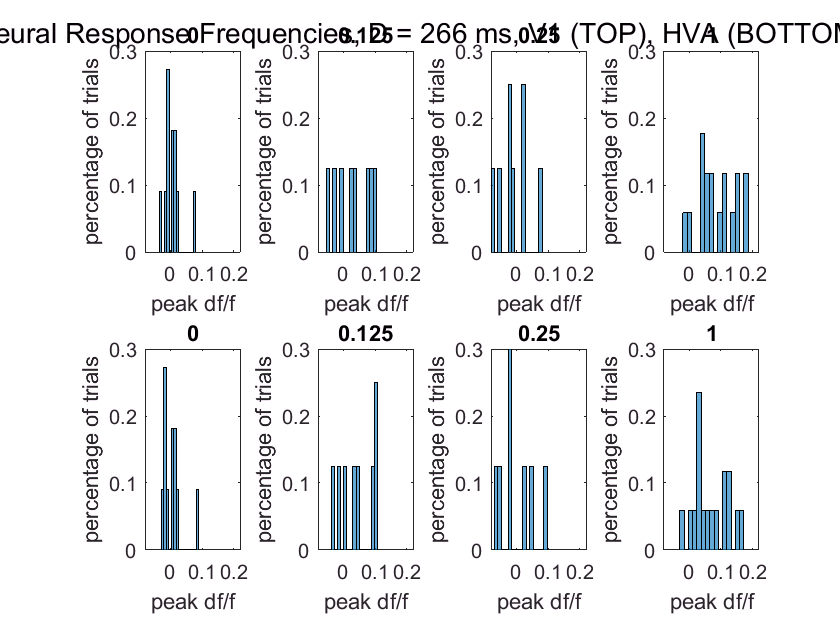

% HISTOS

% HISTO, V1, 266ms, 3 CONS

clear loopCounter
loopCounter = 1;

figure % make one figure for all subplots of each contrast
clear titleText
titleText = sprintf(': Frequency of Response Magnitudes for D = 266 ms \n TOP = V1, BOTTOM = HVA'); % making char variables for sprintf/title later
% suptitle(sprintf('%s', date, subjName, titleText));
suptitle('Neural Response Frequencies, D = 266 ms, V1 (TOP), HVA (BOTTOM)')

%for i = 1:length(xpts) % for each point make a figure
for i = 1 % for V1
    
    for d = 5 % the duration param that corresponds to 266 ms
    
    % making the subplots for each contrast
    % for c = 1:length(uniqueContrasts) % for each contrast
    for c = [1 4 5 7]
        
        clear sqOneFrameOverTrialsPTSdfof
        
        % get the DTH CTH TRIALS
        
        clear cthDthTrials
        cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d); % 5th dur param (4 frames, 266 ms)
        numTrials = sum(cthDthTrials);
        
%         % get the CTH TRIALS
%         clear cthTrials
%         cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c);

        % take df/f data for ith pt, peak frames, cth dth trials
        allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,cthDthTrials)); 
        meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
        % ^ CANT do: store output vectors for each contrast
        % b/c every vectoris a different length (num trials), so can't 'collect'
        % Better to just plot directly on the subplot here
        
        % get BASELINE @ cth trials
        clear allBaselineFrames
        allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,cthDthTrials));
        % get one mean baseline value over all frames & trials
        meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
        meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
        
        % SUBTract BASeline from vector of mean df/f for peak frames, for all cth trials
        meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
        
        subplot(2,4,loopCounter) % make a subplot for each contrast
        %title(sprintf('c = %0.3d',contrasts(c)))
        
        numBins = 15;
        % histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins)
        histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins,'Normalization','probability')
        title(uniqueContrasts(c))
        xlabel('peak df/f')
        ylabel('percentage of trials')
        ylim([0 0.3])
        xlim([-0.08 0.22])
        
        loopCounter = loopCounter + 1;
        
        hold on  
        
    end % end c loop
    
    end % end d loop
       
end % end i loop

hold on % same figure, diff point

% HISTO, PT3, 266ms, 3 CONS

clear loopCounter
loopCounter = 5;

% figure % make one figure for all subplots of each contrast
% clear titleText
% titleText = sprintf(': Frequency of Response Magnitudes for D = 266 ms \n Each Contrast, V1'); % making char variables for sprintf/title later
% suptitle(sprintf('%s', date, subjName, titleText));

%for i = 1:length(xpts) % for each point make a figure
for i = 3 % for PT3
    
    for d = 5 % the duration param that corresponds to 266 ms
    
    % making the subplots for each contrast
    % for c = 1:length(uniqueContrasts) % for each contrast
    for c = [1 4 5 7]
        
        clear sqOneFrameOverTrialsPTSdfof
        
        % get the DTH CTH TRIALS
        
        clear cthDthTrials
        cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d); % 5th dur param (4 frames, 266 ms)
        numTrials = sum(cthDthTrials);
        
%         % get the CTH TRIALS
%         clear cthTrials
%         cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c);

        % take df/f data for ith pt, peak frames, cth dth trials
        allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,cthDthTrials)); 
        meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
        % ^ CANT do: store output vectors for each contrast
        % b/c every vectoris a different length (num trials), so can't 'collect'
        % Better to just plot directly on the subplot here
        
        % get BASELINE @ cth trials
        clear allBaselineFrames
        allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,cthDthTrials));
        % get one mean baseline value over all frames & trials
        meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
        meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
        
        % SUBTract BASeline from vector of mean df/f for peak frames, for all cth trials
        meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
        
        subplot(2,4,loopCounter) % make a subplot for each contrast
        %title(sprintf('c = %0.3d',contrasts(c)))
        
        numBins = 15;
        % histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins)
        histogram(meanPeakFramesCthDthTrialsIthPtMinusBase,numBins,'Normalization','probability')
        title(uniqueContrasts(c))
        xlabel('peak df/f')
        ylabel('percentage of trials')
        ylim([0 0.3])
        xlim([-0.08 0.22])
        
        loopCounter = loopCounter + 1;
        
        hold on  
        
    end % end c loop
    
    end % end d loop
       
end % end i loop

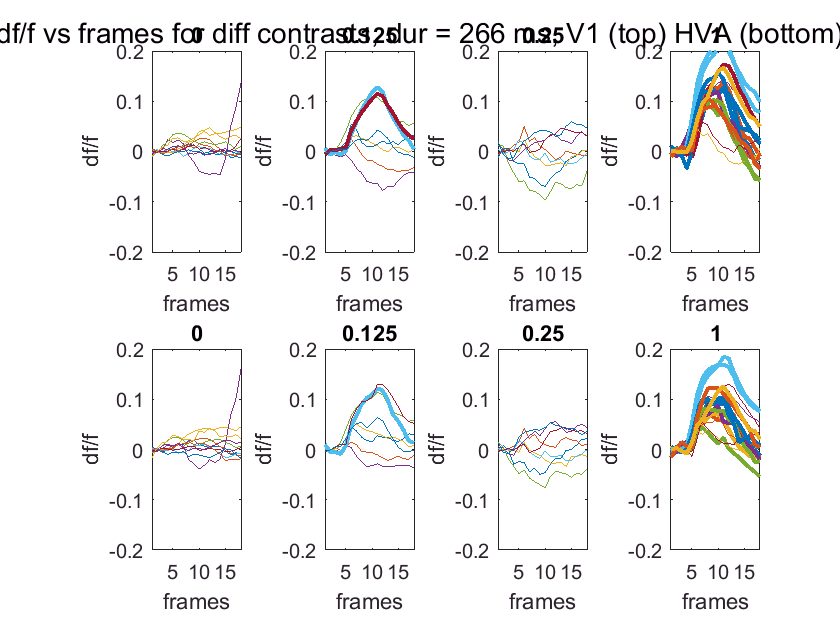

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% V1
% D = 266 ms
% C = 0, 0.125, 0.25, 1

figure % make one figure for all subplots
clear titleText
titleText = ': df/f vs frames for diff contrasts, dur = 266 ms, V1 (top) HVA (bottom), ~ 40 trials/condition'; % making char variables for sprintf/title later
% suptitle(sprintf('%s', date, subjName, titleText));
suptitle('df/f vs frames for diff contrasts, dur = 266 ms, V1 (top) HVA (bottom)')

clear loopCounter
loopCounter = 1;
 
clear i
% for i = 1:length(xPickedPts) % for each point
for i = 1
    
    for d = 5
        
        for c = [1 4 5 7]
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,cthDthTrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
            for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
            % getting TRIAL VECTOR
            clear onePtAllFramesOneTrial % make new var for each trial
            % index into each trace/vector & save as variable
            onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
            % getting MEAN BASEline VALUE for each TRIAL
            clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
            % collect 4 baseline frames for tr-th ith trial
            allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
            clear mean4baseFramesOnePtOneTrial
            % get mean value of baseline values for ith point
            mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
            mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
            % BASEline CORRECTion of TRIAL VECTOR
            % new baseline-corrected trace for each trial
            onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
            
            peak2post = max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx)) - min(onePtAllFramesOneTrialMinusMeanBase(1,12:end));
        
            % collect CORRECTed TRIAL VECTORS in matrix
            % (only clear this outside the loop for each point)
            recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            
            % plot one baseline corrected trace at a time
            subplot(2,4,loopCounter)
            
            if peak2post >= 0.09
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase,'linewidth',2)
                title(uniqueContrasts(c))
                
            else 
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                title(uniqueContrasts(c))
                
            end 
                
            hold on % hold for next trial
                
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
        ylim([-0.2 0.2]) 
        xlim([1 length(x_axis)])
        ylabel('df/f')
        xlabel('frames')

        ax = gca;
        x.XTick = [1:1:length(x_axis)];
        
        loopCounter = loopCounter + 1;
        
        end % end c loop
        
    end % end d loop
       
end % end i loop

hold on % same fig

clear loopCounter
loopCounter = 5;
 
clear i
% for i = 1:length(xPickedPts) % for each point
for i = 3 
    
    for d = 5
        
        for c = [1 4 5 7]
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,cthDthTrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
            for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
            % getting TRIAL VECTOR
            clear onePtAllFramesOneTrial % make new var for each trial
            % index into each trace/vector & save as variable
            onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
            % getting MEAN BASEline VALUE for each TRIAL
            clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
            % collect 4 baseline frames for tr-th ith trial
            allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
            clear mean4baseFramesOnePtOneTrial
            % get mean value of baseline values for ith point
            mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
            mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
            % BASEline CORRECTion of TRIAL VECTOR
            % new baseline-corrected trace for each trial
            onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
            
            peak2post = max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx)) - min(onePtAllFramesOneTrialMinusMeanBase(1,12:end));
        
            % collect CORRECTed TRIAL VECTORS in matrix
            % (only clear this outside the loop for each point)
            recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            
            % plot one baseline corrected trace at a time
            subplot(2,4,loopCounter)
            
            if peak2post >= 0.09
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase,'linewidth',2)
                title(uniqueContrasts(c))
                
            else 
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                title(uniqueContrasts(c))
                
            end 
                
            hold on % hold for next trial
                
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
        ylim([-0.2 0.2]) 
        xlim([1 length(x_axis)])
        ylabel('df/f')
        xlabel('frames')

        ax = gca;
        x.XTick = [1:1:length(x_axis)];
        
        loopCounter = loopCounter + 1;
        
        end % end c loop
        
    end % end d loop
       
end % end i loop

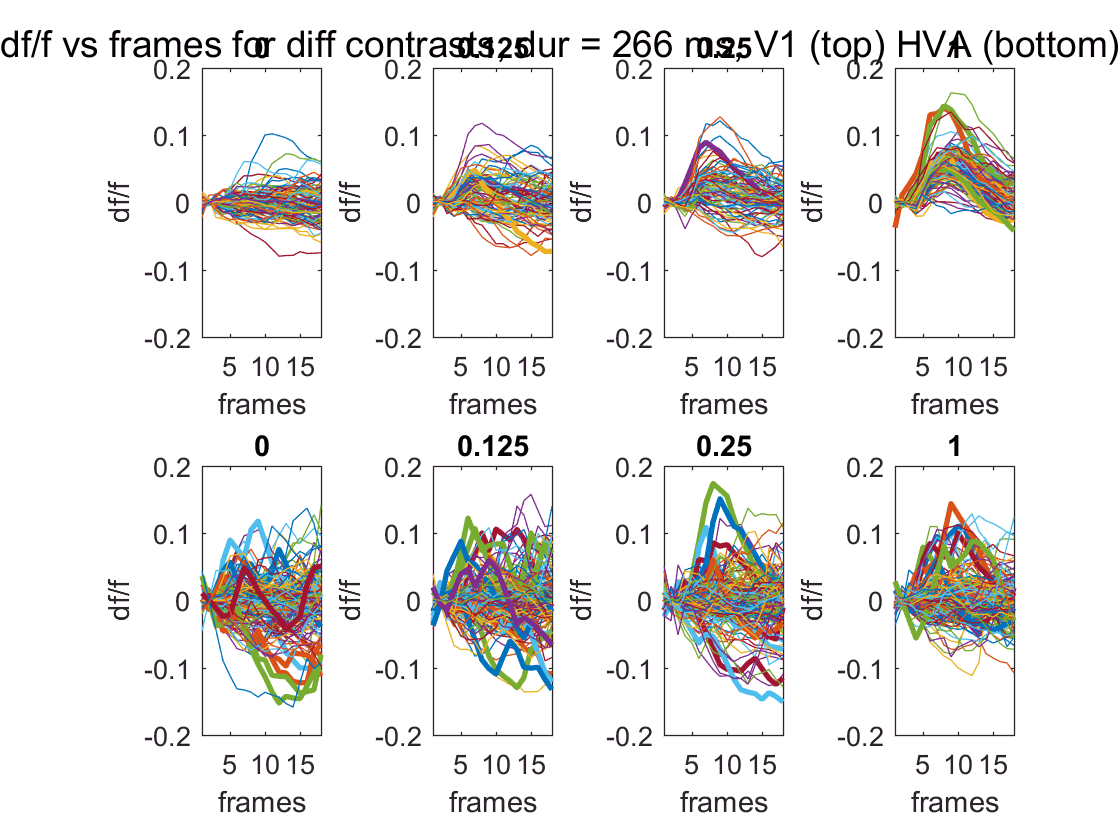

% BY PUPIL SIZE (large)

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% V1
% D = 266 ms
% C = 0, 0.125, 0.25, 1

figure % make one figure for all subplots
clear titleText
titleText = ': df/f vs frames for diff contrasts, dur = 266 ms, V1 (top) HVA (bottom), ~ 40 trials/condition'; % making char variables for sprintf/title later
% suptitle(sprintf('%s', date, subjName, titleText));
suptitle('df/f vs frames for diff contrasts, dur = 266 ms, V1 (top) HVA (bottom)')

clear loopCounter
loopCounter = 1;
 
clear i
% for i = 1:length(xPickedPts) % for each point
for i = 1
    
    for d = 1
        
        for c = [1 4 5 7]
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            % NEW part
            
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             cthDthTrials = intersect(idxCthDthTrial,idxLargePupilTrials);
             
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,cthDthTrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
            for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
            % getting TRIAL VECTOR
            clear onePtAllFramesOneTrial % make new var for each trial
            % index into each trace/vector & save as variable
            onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
            % getting MEAN BASEline VALUE for each TRIAL
            clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
            % collect 4 baseline frames for tr-th ith trial
            allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
            clear mean4baseFramesOnePtOneTrial
            % get mean value of baseline values for ith point
            mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
            mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
            % BASEline CORRECTion of TRIAL VECTOR
            % new baseline-corrected trace for each trial
            onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
            
            peak2post = max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx)) - min(onePtAllFramesOneTrialMinusMeanBase(1,12:end));
        
            % collect CORRECTed TRIAL VECTORS in matrix
            % (only clear this outside the loop for each point)
            recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            
            % plot one baseline corrected trace at a time
            subplot(2,4,loopCounter)
            
            if peak2post >= 0.09
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase,'linewidth',2)
                title(uniqueContrasts(c))
                
            else 
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                title(uniqueContrasts(c))
                
            end 
                
            hold on % hold for next trial
                
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
        ylim([-0.2 0.2]) 
        xlim([1 length(x_axis)])
        ylabel('df/f')
        xlabel('frames')

        ax = gca;
        x.XTick = [1:1:length(x_axis)];
        
        loopCounter = loopCounter + 1;
        
        end % end c loop
        
    end % end d loop
       
end % end i loop

hold on % same fig

clear loopCounter
loopCounter = 5;
 
clear i
% for i = 1:length(xPickedPts) % for each point
for i = 2 
    
    for d = 1
        
        for c = [1 4 5 7]
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,cthDthTrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
            for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
            % getting TRIAL VECTOR
            clear onePtAllFramesOneTrial % make new var for each trial
            % index into each trace/vector & save as variable
            onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
            % getting MEAN BASEline VALUE for each TRIAL
            clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
            % collect 4 baseline frames for tr-th ith trial
            allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
            clear mean4baseFramesOnePtOneTrial
            % get mean value of baseline values for ith point
            mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
            mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
            % BASEline CORRECTion of TRIAL VECTOR
            % new baseline-corrected trace for each trial
            onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
            
            peak2post = max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx)) - min(onePtAllFramesOneTrialMinusMeanBase(1,12:end));
        
            % collect CORRECTed TRIAL VECTORS in matrix
            % (only clear this outside the loop for each point)
            recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            
            % plot one baseline corrected trace at a time
            subplot(2,4,loopCounter)
            
            if peak2post >= 0.09
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase,'linewidth',2)
                title(uniqueContrasts(c))
                
            else 
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                title(uniqueContrasts(c))
                
            end 
                
            hold on % hold for next trial
                
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
        ylim([-0.2 0.2]) 
        xlim([1 length(x_axis)])
        ylabel('df/f')
        xlabel('frames')

        ax = gca;
        x.XTick = [1:1:length(x_axis)];
        
        loopCounter = loopCounter + 1;
        
        end % end c loop
        
    end % end d loop
       
end % end i loop

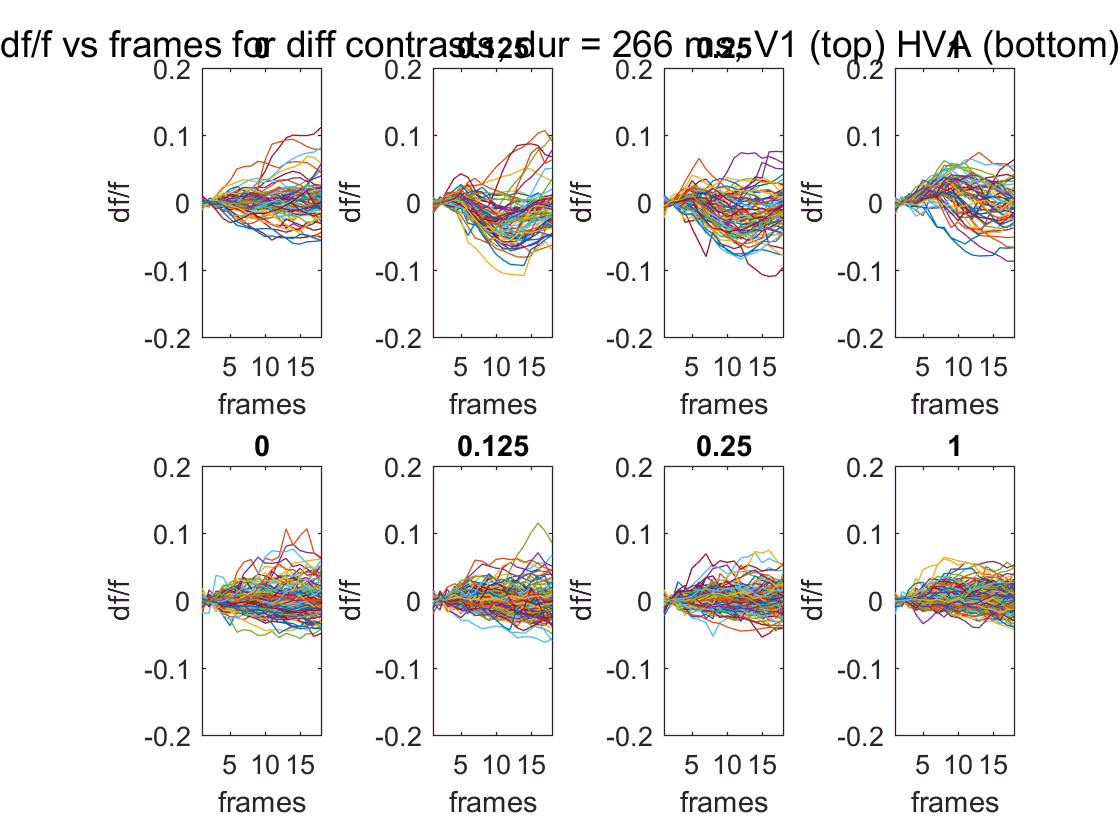

% BY PUPIL SIZE (large)

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% V1
% D = 266 ms
% C = 0, 0.125, 0.25, 1

figure % make one figure for all subplots
clear titleText
titleText = ': df/f vs frames for diff contrasts, dur = 266 ms, V1 (top) HVA (bottom), ~ 40 trials/condition'; % making char variables for sprintf/title later
% suptitle(sprintf('%s', date, subjName, titleText));
suptitle('df/f vs frames for diff contrasts, dur = 266 ms, V1 (top) HVA (bottom)')

clear loopCounter
loopCounter = 1;
 
clear i
% for i = 1:length(xPickedPts) % for each point
for i = 1
    
    for d = 1
        
        for c = [1 4 5 7]
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            % NEW part
            
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             cthDthTrials = intersect(idxCthDthTrial,idxSmallPupilTrials);
             
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,cthDthTrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
            for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
            % getting TRIAL VECTOR
            clear onePtAllFramesOneTrial % make new var for each trial
            % index into each trace/vector & save as variable
            onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
            % getting MEAN BASEline VALUE for each TRIAL
            clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
            % collect 4 baseline frames for tr-th ith trial
            allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
            clear mean4baseFramesOnePtOneTrial
            % get mean value of baseline values for ith point
            mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
            mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
            % BASEline CORRECTion of TRIAL VECTOR
            % new baseline-corrected trace for each trial
            onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
            
            peak2post = max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx)) - min(onePtAllFramesOneTrialMinusMeanBase(1,12:end));
        
            % collect CORRECTed TRIAL VECTORS in matrix
            % (only clear this outside the loop for each point)
            recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            
            % plot one baseline corrected trace at a time
            subplot(2,4,loopCounter)
            
            if peak2post >= 0.09
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase,'linewidth',2)
                title(uniqueContrasts(c))
                
            else 
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                title(uniqueContrasts(c))
                
            end 
                
            hold on % hold for next trial
                
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
        ylim([-0.2 0.2]) 
        xlim([1 length(x_axis)])
        ylabel('df/f')
        xlabel('frames')

        ax = gca;
        x.XTick = [1:1:length(x_axis)];
        
        loopCounter = loopCounter + 1;
        
        end % end c loop
        
    end % end d loop
       
end % end i loop

hold on % same fig

clear loopCounter
loopCounter = 5;
 
clear i
% for i = 1:length(xPickedPts) % for each point
for i = 3 
    
    for d = 1
        
        for c = [1 4 5 7]
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,cthDthTrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
            for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
            % getting TRIAL VECTOR
            clear onePtAllFramesOneTrial % make new var for each trial
            % index into each trace/vector & save as variable
            onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
            % getting MEAN BASEline VALUE for each TRIAL
            clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
            % collect 4 baseline frames for tr-th ith trial
            allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
            clear mean4baseFramesOnePtOneTrial
            % get mean value of baseline values for ith point
            mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
            mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
            % BASEline CORRECTion of TRIAL VECTOR
            % new baseline-corrected trace for each trial
            onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
            
            peak2post = max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx)) - min(onePtAllFramesOneTrialMinusMeanBase(1,12:end));
        
            % collect CORRECTed TRIAL VECTORS in matrix
            % (only clear this outside the loop for each point)
            recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            
            % plot one baseline corrected trace at a time
            subplot(2,4,loopCounter)
            
            if peak2post >= 0.09
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase,'linewidth',2)
                title(uniqueContrasts(c))
                
            else 
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                title(uniqueContrasts(c))
                
            end 
                
            hold on % hold for next trial
                
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
        ylim([-0.2 0.2]) 
        xlim([1 length(x_axis)])
        ylabel('df/f')
        xlabel('frames')

        ax = gca;
        x.XTick = [1:1:length(x_axis)];
        
        loopCounter = loopCounter + 1;
        
        end % end c loop
        
    end % end d loop
       
end % end i loop